Forecast monthly runoff with ARIMA

## 1 Clear workspace

clear
close all
clc

## 2 Read monthly runoff

data_path='../time_series/';
station='Huaxian' %'Huaxian', 'Xianyang' or 'Zhangjiashan'

station = 'Huaxian'

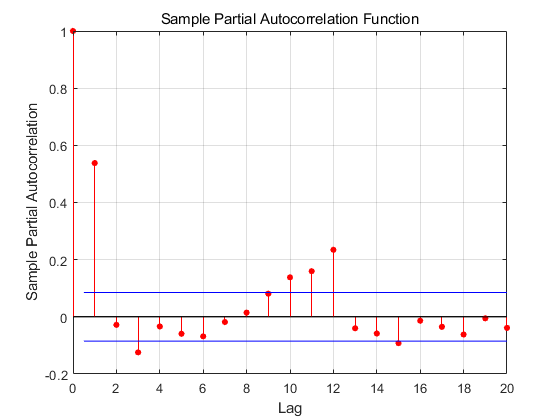

switch station
    case 'Huaxian'
        save_path = '../Huaxian/projects/arma/';
        data = xlsread([data_path,'HuaxianRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
    
    case 'Xianyang'
        save_path = '../Xianyang/projects/arma/';
        data = xlsread([data_path,'XianyangRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
        
    case 'Zhangjiashan'
        save_path = '../Zhangjiashan/projects/arma/';
        data = xlsread([data_path,'ZhangJiaShanRunoff1953-2018(1953-2018).xlsx'],1,'B2:B793');%full=792samples
end

if exist(save_path,'dir')==0
   mkdir(save_path);
end

train_len = 552;
dev_len=120;
test_len=120;

train = data(1:train_len);
dev = data(train_len+1:train_len+dev_len);
test = data(train_len+dev_len+1:length(data));

parcorr(train)

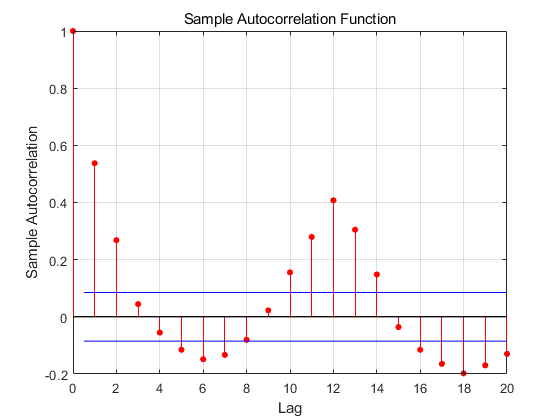

autocorr(train)

## 3 Tune ARIMA models

tic
mse = zeros(20,20);
parfor p =1:20
    for q=1:20
        m = armax(train,[p,q]);
        dev_pred = predict(m,dev,1);
        mse(p,q)= (sum((dev-dev_pred).^2)/length(dev));
    end
end
elapsedTime = toc

elapsedTime = 59.9270

## 4 Predict the train, dev and test set

minimum = min(min(mse));
[p_,q_]=find(mse==minimum);
m = armax(train,[p_,q_]);
train_pred = predict(m,train,1);
dev_pred = predict(m,dev,1);
test_pred = predict(m,test);

train_pred(train_pred<0)=0;
dev_pred(dev_pred<0)=0;
test_pred(test_pred<0)=0;

nse_train = NSE(train,train_pred);
nse_dev = NSE(dev,dev_pred);
nse_test = NSE(test,test_pred);

nrmse_train =NRMSE(train,train_pred);
nrmse_dev = NRMSE(dev,dev_pred);
nrmse_test = NRMSE(test,test_pred);

ppts_train = PPTS(train,train_pred,5);

y_true_ =    43.7901
   40.1760
   38.5716
   36.7589
   36.6284
   34.7933
   34.3760
   31.6051
   29.2352
   29.0805


y_true_order =    141
    68
   274
   345
   370
   189
   142
    55
   106
   381


y_pred_ =    18.8639
   18.1571
   15.9707
   18.9090
   14.6656
   17.2135
   25.1668
   16.4600
    7.5431
   17.0888


ppts_dev = PPTS(dev,dev_pred,5);

y_true_ =    29.8279
   25.1165
   13.4997
   11.8809
   11.2257
   10.6223
   10.1503
    7.7388
    7.5529
    7.5077


y_true_order =     58
    82
     7
   106
    56
    22
    80
   104
    79
   103


y_pred_ =     8.9970
   10.5801
    7.4851
   10.3341
    5.9735
    7.5680
    9.8528
   10.6004
    3.2440
    2.4909


ppts_test = PPTS(test,test_pred,5);

y_true_ =    32.3767
   24.7216
   18.6783
   15.8656
   14.9455
   13.2451
   13.0836
   11.1387
   10.3715
    9.4003


y_true_order =     33
   115
    55
    20
   106
    69
    45
    21
    34
    56


y_pred_ =    14.9301
    6.8902
    9.6052
    9.8569
    4.9499
    9.2181
   12.9479
   12.5022
   16.0468
   12.9881


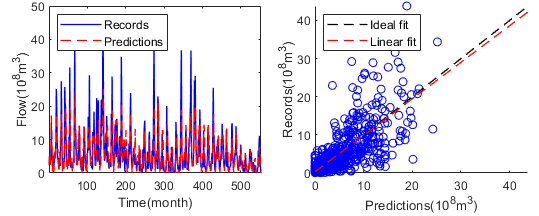

ha =     1.0004
    2.0004


x =          0    0.4423    0.8846    1.3270    1.7693    2.2116    2.6539    3.0963    3.5386    3.9809    4.4232    4.8656    5.3079    5.7502    6.1925    6.6349    7.0772    7.5195    7.9618    8.4042    8.8465    9.2888    9.7311   10.1735   10.6158   11.0581   11.5004   11.9428   12.3851   12.8274   13.2697   13.7121   14.1544   14.5967   15.0390   15.4814   15.9237   16.3660   16.8083   17.2507   17.6930   18.1353   18.5776   19.0199   19.4623   19.9046   20.3469   20.7892   21.2316   21.6739


c =     0.9578    0.2971


y =     0.2971    0.7207    1.1444    1.5681    1.9918    2.4154    2.8391    3.2628    3.6864    4.1101    4.5338    4.9575    5.3811    5.8048    6.2285    6.6522    7.0758    7.4995    7.9232    8.3469    8.7705    9.1942    9.6179   10.0415   10.4652   10.8889   11.3126   11.7362   12.1599   12.5836   13.0073   13.4309   13.8546   14.2783   14.7019   15.1256   15.5493   15.9730   16.3966   16.8203   17.2440   17.6677   18.0913   18.5150   18.9387   19.3624   19.7860   20.2097   20.6334   21.0570


y = 0.95783*x + 0.29706


错误使用 saveas (line 179)
不支持的格式或扩展名: -r300

出错 plot_pred (line 43)
saveas(gcf,file_name,'-r300');


metrics=[p_,q_,elapsedTime,nse_train,nrmse_train,ppts_train,nse_dev,nrmse_dev,ppts_dev,nse_test,nrmse_test,ppts_test];
metrics_table = array2table(metrics, 'VariableNames', {'p','q','time_cost','train_nse','train_nrmse','train_ppts','dev_nse','dev_nrmse','dev_ppts','test_nse','test_nrmse','test_ppts'});
writetable(metrics_table, strcat(save_path,'metrics.csv'));
train_results=[train,train_pred];
dev_results=[dev,dev_pred];
test_results=[test,test_pred];
train_table=array2table(train_results, 'VariableNames',{'train_y','train_pred'});
dev_table=array2table(dev_results, 'VariableNames',{'dev_y','dev_pred'});
test_table=array2table(test_results, 'VariableNames',{'test_y','test_pred'});
writetable(train_table, strcat(save_path,'train_pred.csv'));
writetable(dev_table, strcat(save_path,'dev_pred.csv'));
writetable(test_table, strcat(save_path,'test_pred.csv'));

plot_pred(train,train_pred,strcat(save_path,'train_pred.png'))

plot_pred(dev,dev_pred,strcat(save_path,'dev_pred.png'))
plot_pred(test,test_pred,strcat(save_path,'test_pred.png'))
